# State Space Models

We begin by writing the state space model for a an *individual (Ai)* axis

syms I I_dot theta_ddot_g V_s R_m L_m V_emf theta_dot_m tau_m G theta_dot_g b J K_e K_i

u_i = V_s

$$u\_i = V_{s}$$


x_i = [
    I
    theta_dot_g
]

$$x\_i = \left(\begin{array}{c} \text{I}\\ {\dot{\theta }}_{g} \end{array}\right)$$


x_dot_i = [
    I_dot
    theta_ddot_g
]

$$x\_dot\_i = \left(\begin{array}{c} \dot{I}\\ {\ddot{\theta }}_{g} \end{array}\right)$$


A_i = [
    -R_m/L_m    -K_e/(L_m*G);
    -K_i/(J*G)  b/J
]

$$A\_i = \left(\begin{array}{cc} -\frac{R_{m}}{L_{m}} & -\frac{K_{e}}{G\,L_{m}}\\ -\frac{K_{i}}{G\,J} & \frac{b}{J} \end{array}\right)$$

B_i = [
    1/L_m;
    0
]

$$B\_i = \left(\begin{array}{c} \frac{1}{L_{m}}\\ 0 \end{array}\right)$$

## State Space Models for Individual Axis

syms I_pan  I_dot_pan  theta_ddot_m_pan  V_s_pan R_m_pan L_m_pan V_emf_pan theta_dot_m_pan tau_m_pan G_pan theta_dot_g_pan b_pan J_pan K_e_pan K_i_pan
syms I_tilt I_dot_tilt theta_ddot_m_tilt V_s_tilt R_m_tilt L_m_tilt V_emf_tilt theta_dot_m_tilt tau_m_tilt G_tilt theta_dot_g_tilt b_tilt J_tilt K_e_tilt K_i_tilt

s      = [ I      I_dot      theta_ddot_m      V_s      R_m L_m V_emf theta_dot_m      tau_m      G      theta_dot_g      b      J      K_e K_i ];
s_pan  = [ I_pan  I_dot_pan  theta_ddot_m_pan  V_s_pan  R_m L_m V_emf theta_dot_m_pan  tau_m_pan  G_pan  theta_dot_g_pan  b_pan  J_pan  K_e K_i ];
s_tilt = [ I_tilt I_dot_tilt theta_ddot_m_tilt V_s_tilt R_m L_m V_emf theta_dot_m_tilt tau_m_tilt G_tilt theta_dot_g_tilt b_tilt J_tilt K_e K_i ];


x_pan  = subs(x_i, s, s_pan)

$$x\_pan = \left(\begin{array}{c} I_{\mathrm{pan}}\\ {\dot{\theta }}_{g,\mathrm{pan}} \end{array}\right)$$

x_tilt = subs(x_i, s, s_tilt)

$$x\_tilt = \left(\begin{array}{c} I_{\mathrm{tilt}}\\ {\dot{\theta }}_{g,\mathrm{tilt}} \end{array}\right)$$


x_dot_pan  = subs(x_dot_i, s, s_pan);
x_dot_tilt = subs(x_dot_i, s, s_tilt);

u_pan  = subs(u_i, s, s_pan);
u_tilt = subs(u_i, s, s_tilt);

A_pan  = subs(A_i, s, s_pan)

$$A\_pan = \left(\begin{array}{cc} -\frac{R_{m}}{L_{m}} & -\frac{K_{e}}{G_{\mathrm{pan}}\,L_{m}}\\ -\frac{K_{i}}{G_{\mathrm{pan}}\,J_{\mathrm{pan}}} & \frac{b_{\mathrm{pan}}}{J_{\mathrm{pan}}} \end{array}\right)$$

A_tilt  = subs(A_i, s, s_tilt)

$$A\_tilt = \left(\begin{array}{cc} -\frac{R_{m}}{L_{m}} & -\frac{K_{e}}{G_{\mathrm{tilt}}\,L_{m}}\\ -\frac{K_{i}}{G_{\mathrm{tilt}}\,J_{\mathrm{tilt}}} & \frac{b_{\mathrm{tilt}}}{J_{\mathrm{tilt}}} \end{array}\right)$$

B_pan  = subs(B_i, s, s_pan)

$$B\_pan = \left(\begin{array}{c} \frac{1}{L_{m}}\\ 0 \end{array}\right)$$

B_tilt  = subs(B_i, s, s_tilt)

$$B\_tilt = \left(\begin{array}{c} \frac{1}{L_{m}}\\ 0 \end{array}\right)$$

We can now combine these into one large model

x = [ x_pan; x_tilt ]

$$x = \left(\begin{array}{c} I_{\mathrm{pan}}\\ {\dot{\theta }}_{g,\mathrm{pan}}\\ I_{\mathrm{tilt}}\\ {\dot{\theta }}_{g,\mathrm{tilt}} \end{array}\right)$$

x_dot = [ x_dot_pan; x_dot_tilt ]

$$x\_dot = \left(\begin{array}{c} {\dot{I}}_{\mathrm{pan}}\\ {\ddot{\theta }}_{g}\\ {\dot{I}}_{\mathrm{tilt}}\\ {\ddot{\theta }}_{g} \end{array}\right)$$


A = [
    A_pan    zeros(2);
    zeros(2) A_tilt
]

$$A = \left(\begin{array}{cccc} -\frac{R_{m}}{L_{m}} & -\frac{K_{e}}{G_{\mathrm{pan}}\,L_{m}} & 0 & 0\\ -\frac{K_{i}}{G_{\mathrm{pan}}\,J_{\mathrm{pan}}} & \frac{b_{\mathrm{pan}}}{J_{\mathrm{pan}}} & 0 & 0\\ 0 & 0 & -\frac{R_{m}}{L_{m}} & -\frac{K_{e}}{G_{\mathrm{tilt}}\,L_{m}}\\ 0 & 0 & -\frac{K_{i}}{G_{\mathrm{tilt}}\,J_{\mathrm{tilt}}} & \frac{b_{\mathrm{tilt}}}{J_{\mathrm{tilt}}} \end{array}\right)$$

B = [
    B_pan              zeros(size(B_pan));
    zeros(size(B_pan)) B_tilt
]

$$B = \left(\begin{array}{cc} \frac{1}{L_{m}} & 0\\ 0 & 0\\ 0 & \frac{1}{L_{m}}\\ 0 & 0 \end{array}\right)$$

% Defining outputs to be the velocities
C = [
    0 1 0 0;
    0 0 0 1
];
D = 0;

u = [ u_pan; u_tilt ]

$$u = \left(\begin{array}{c} V_{s,\mathrm{pan}}\\ V_{s,\mathrm{tilt}} \end{array}\right)$$

## Adding Real Parameters

G_tilt_real = 15/48; % measured by counting gear teeth on the system
G_pan_real = G_tilt_real;

% Use moment of inertia calculated in 'inertia.mlx'
J_tilt_real = vpa(J_tilt_real)

$$J\_tilt\_real = 0.021253995$$

J_pan_real = vpa(J_pan_real)

$$J\_pan\_real = 0.0433130440995\,{\sin\left(\theta_{\mathrm{tilt}}\right)}^{2}+0.059756512932$$

% Motor constants (K_e = K_i in SI units)
K_i_real = 0.509;
K_e_real = K_i_real;
R_m_real = 7.101;
L_m_real = 3.4E-3;

% Friction coefficients
b_pan_real  = 0 % TODO: system identification

b_pan_real = 0

b_tilt_real = 0 % TODO: system identification

b_tilt_real = 0



% substitute into the model
s      = [ b_pan      b_tilt      L_m      G_pan      b_pan J_pan      K_e_pan  R_m      L_m_tilt G_tilt      b_tilt J_tilt      K_e      K_i      ];
s_real = [ b_pan_real b_tilt_real L_m_real G_pan_real b_pan J_pan_real K_e_real R_m_real L_m_real G_tilt_real b_tilt J_tilt_real K_e_real K_i_real ];

A_real = vpa(subs(A, s, s_real), 3)

$$A\_real = \left(\begin{array}{cccc} -2090.0 & -479.0 & 0 & 0\\ -\frac{1.63}{0.0433\,{\sin\left(\theta_{\mathrm{tilt}}\right)}^{2}+0.0598} & 0 & 0 & 0\\ 0 & 0 & -2090.0 & -479.0\\ 0 & 0 & -76.6 & 0 \end{array}\right)$$

B_real = vpa(subs(B, s, s_real), 4)

$$B\_real = \left(\begin{array}{cc} 294.1 & 0\\ 0 & 0\\ 0 & 294.1\\ 0 & 0 \end{array}\right)$$

y = C*x + D*u

$$y = \left(\begin{array}{c} {\dot{\theta }}_{g,\mathrm{pan}}\\ {\dot{\theta }}_{g,\mathrm{tilt}} \end{array}\right)$$

# Controlability

Con = [B_real A_real*B_real];
rank(Con)

ans = 4

The system is controlable as the controlability has rank equal to the number of system state variables

# Regulator - State Feedback

t_s = 1;
alpha = 5;
sigma = -log(alpha/100)/t_s

sigma = 2.9957

A_e = [
        A_real zeros(4,2);
        C zeros(2,2);
   ]

$$A\_e = \left(\begin{array}{cccccc} -2088.529411792755126953125 & -479.058823525905609130859375 & 0 & 0 & 0 & 0\\ -\frac{1.6288000000058673322200775146484}{0.0433130440995\,{\sin\left(\theta_{\mathrm{tilt}}\right)}^{2}+0.059756512932} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -2088.529411792755126953125 & -479.058823525905609130859375 & 0 & 0\\ 0 & 0 & -76.635004383881712590974073344799 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 \end{array}\right)$$

B_e = [
        B_real;
        zeros(2,2);
]

$$B\_e = \left(\begin{array}{cc} 294.117647059261798858642578125 & 0\\ 0 & 0\\ 0 & 294.117647059261798858642578125\\ 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

C_e = [
        C zeros(2,2);
]

C_e =      0     1     0     0     0     0
     0     0     0     1     0     0


## Place Poles

poles = [-5 -5 -6 -6 -7 -7];

%A_e = double(vpa(subs(A_e, theta_tilt, t)))

F_e = @(t) place(double(subs(A_e, theta_tilt, t)), -double(B_e), poles)

F_e = function_handle with value:
    @(t)place(double(subs(A_e,theta_tilt,t)),-double(B_e),poles)


## Plot how each field in Fe changes with respect to theta_tilt

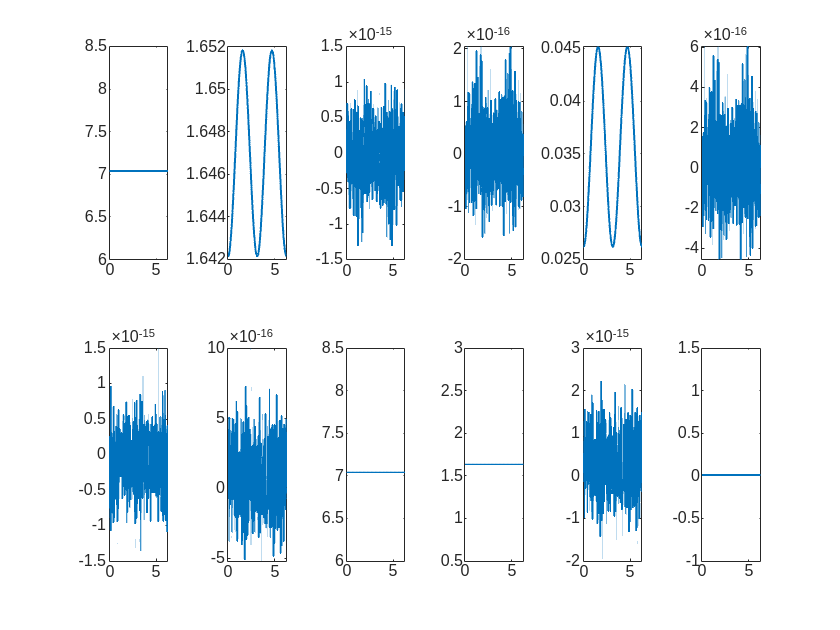

points = [];
for x = 0:0.01:2*pi
    r = F_e(x);
    points = [points [
        x;
        r(1, :)';
        r(2, :)';
    ]];
end

x = points(1, :);
t = tiledlayout(2, 6);
for i = 2:13
    y = points(i, :);
    nexttile
    plot(x, vpa(y, 3), 'LineWidth',1);
    xlim([0 2*pi]);
end
   

set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0 0 15 6]);
fig = gcf;
saveas(fig,'figures/Fe.png')

Get values for each field

Fe11 = points(2, :);
Fe21 = points(3, :);
Fe31 = points(4, :);
Fe41 = points(5, :);
Fe51 = points(6, :);
Fe61 = points(7, :);

Fe12 = points(8, :);
Fe22 = points(9, :);
Fe32 = points(10, :);
Fe42 = points(11, :);
Fe52 = points(12, :);
Fe62 = points(13, :);

# Fitting the Fields

## Fit to Mean

Fe11_reg = mean( Fe11 );
Fe21_reg = mean( Fe21 );
Fe31_reg = mean( Fe31 );
Fe41_reg = mean( Fe41 );
Fe51_reg = mean( Fe51 );
Fe61_reg = mean( Fe61 );
Fe12_reg = mean( Fe12 );
Fe22_reg = mean( Fe22 );
Fe32_reg = mean( Fe32 );
Fe42_reg = mean( Fe42 );
Fe52_reg = mean( Fe52 );
Fe62_reg = mean( Fe62 );

## Fitting sinusoidal looking fields

modelfun = 'y ~ b1*sin(x1*b2 + b3) + b4';
Fe51_mdl = fitnlm(x, Fe51, modelfun, [1 1 1 0]);
b = Fe51_mdl.Coefficients.Estimate;
Fe51_reg = vpa(b(1) * sin(theta_tilt * b(2) + b(3)) + b(4), 4)

$$Fe51\_reg = 0.03569-0.009493\,\sin\left(2.0\,\theta_{\mathrm{tilt}}-4.712\right)$$

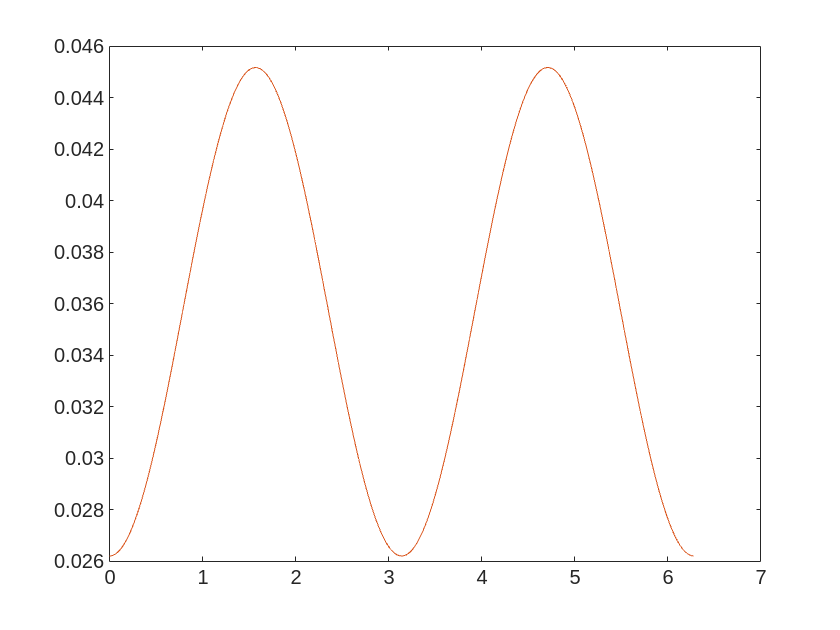

figure
plot(x, Fe51)
hold on
plot(x, subs(Fe51_reg, theta_tilt, x))
hold off

Fe21_mdl = fitnlm(x, Fe21, modelfun, [1 2 1 1.5]);
b = Fe21_mdl.Coefficients.Estimate;
Fe21_reg = vpa(b(1) * sin(theta_tilt * b(2) + b(3)) + b(4), 4)

$$Fe21\_reg = 1.647-0.004837\,\sin\left(2.0\,\theta_{\mathrm{tilt}}+1.571\right)$$

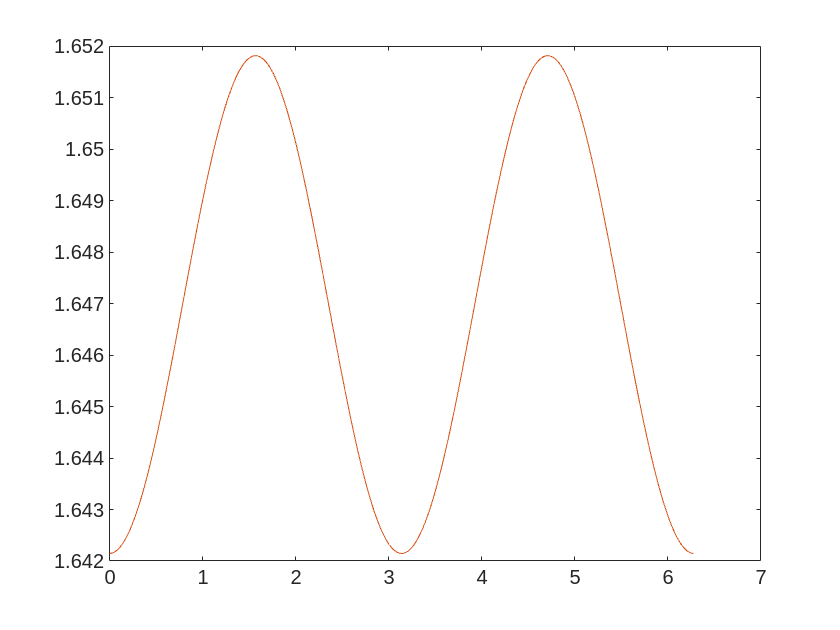

plot(x, Fe21)
hold on
plot(x, subs(Fe21_reg, theta_tilt, x))
hold off

## Assembling the new Fe

F_e_reg = vpa([
    Fe11_reg Fe21_reg Fe31_reg Fe41_reg Fe51_reg Fe61_reg;
    Fe12_reg Fe22_reg Fe32_reg Fe42_reg Fe52_reg Fe62_reg;
], 3)

$$F\_e\_reg = \left(\begin{array}{cccccc} 7.04 & 1.65-0.00484\,\sin\left(2.0\,\theta_{\mathrm{tilt}}+1.57\right) & -2.62e-17 & 3.95e-18 & 0.0357-0.00949\,\sin\left(2.0\,\theta_{\mathrm{tilt}}-4.71\right) & 1.12e-17\\ -8.7e-17 & 7.81e-17 & 7.04 & 1.63 & 3.07e-16 & 0.00932 \end{array}\right)$$

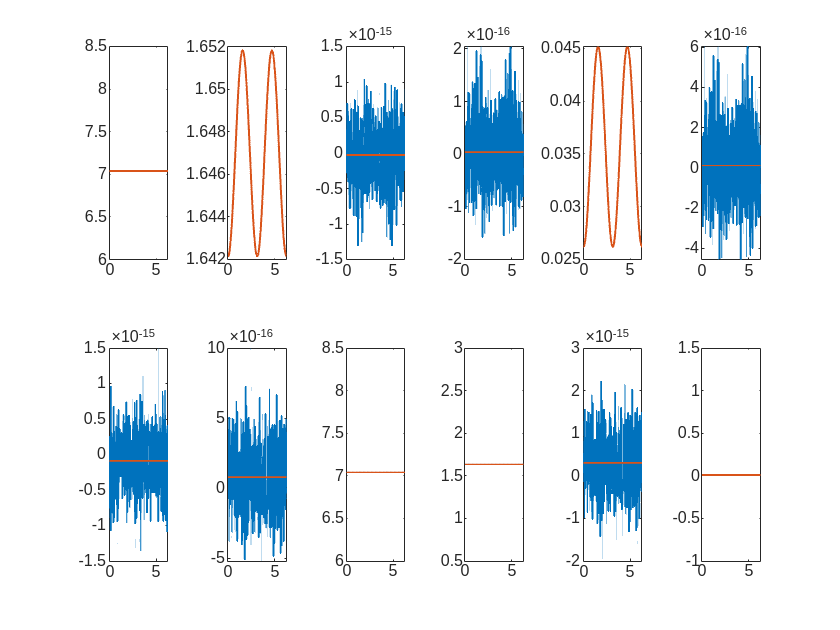

f_reg = @(t) subs(F_e_reg, theta_tilt, t);

step = 0.01;

points = [];
for x = 0:step:2*pi
    r = F_e(x);
    points = [points [
        x;
        r(1, :)';
        r(2, :)';
    ]];
end

reg_points = [];
for x = 0:step:2*pi
    r = f_reg(x);
    reg_points = [reg_points [
        x;
        r(1, :)';
        r(2, :)';
    ]];
end

x = points(1, :);
t = tiledlayout(2, 6);
for i = 2:13
    y = [ points(i, :); reg_points(i, :) ];
    nexttile
    plot(x, vpa(y, 3), 'LineWidth',1);
    xlim([0 2*pi]);
end
   

set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0 0 15 6]);
fig = gcf;
saveas(fig,'figures/Fe_reg.png')

## Split into F and FI

F = vpa(F_e_reg(:, 1:4), 5)

$$F = \left(\begin{array}{cccc} 7.0398 & 1.647-0.0048371\,\sin\left(2.0\,\theta_{\mathrm{tilt}}+1.5708\right) & -2.6208e-17 & 3.9501e-18\\ -8.6955e-17 & 7.8107e-17 & 7.0398 & 1.6335 \end{array}\right)$$

FI = vpa(F_e_reg(:, 5:6), 5)

$$FI = \left(\begin{array}{cc} 0.035688-0.0094933\,\sin\left(2.0\,\theta_{\mathrm{tilt}}-4.7124\right) & 1.1239e-17\\ 3.0675e-16 & 0.0093169 \end{array}\right)$$